## Lab 3. SPECTRAL ESTIMATION IN STATIONARY SIGNALS

### 1. SYNTHETIC TEST SIGNAL

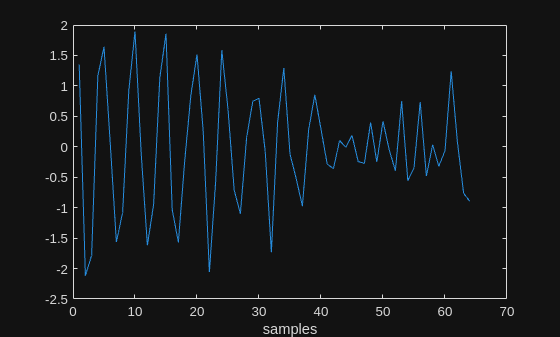

load marple;

% The real part of the signal is selected for the spectral estimation and, 
% then, it is displayed:
marple =real(marple);
plot(marple),
xlabel('samples')

### 1.1. Periodogram

Firstly, the periodogram is calculated (or 'sample spectrum'), and the corresponding Power Spectral Density function estimated from this non-parametric method is displayed:

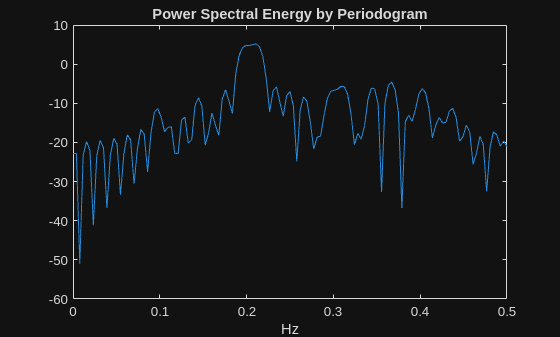

[Pxx,f]=periodogram(marple,[],256,1,'onesided');
plot(f,10*log10((Pxx/2)/(256/64)));
xlabel('Hz');
title('Power Spectral Energy by Periodogram');

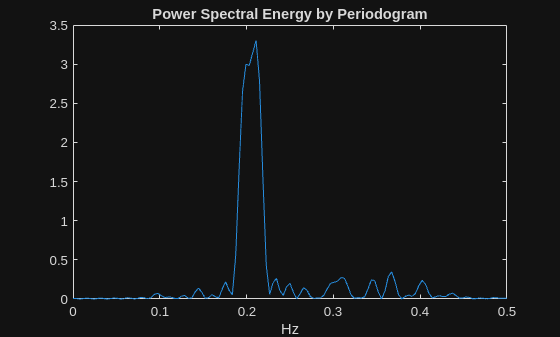

plot(f,(Pxx/2)/(256/64));
xlabel('Hz');
title('Power Spectral Energy by Periodogram');

Alternatively, the periodogram can be calculated directly with the equation using the FFT as follows:

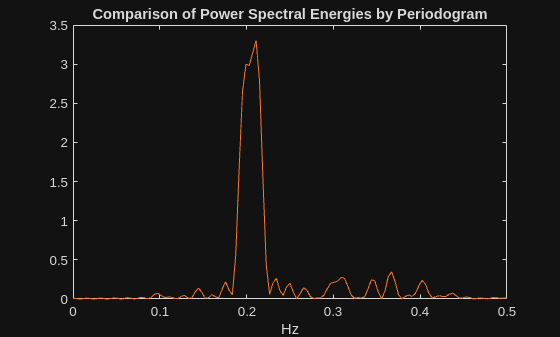

fmarple=fft(marple,256);
Pxxf=abs(fmarple(1:129)).^2/256;
plot(f, (Pxx/2)/(256/64),f,Pxxf);
xlabel('Hz');
title('Comparison of Power Spectral Energies by Periodogram');

Curves are totally overlapped because PSD are the same. To observe the time window effect, we can consider a Hamming window:

wmarple=hamming(length(marple)).*marple;
fwmarple=fft(wmarple,256);
Pxxfw=abs(fwmarple(1:129)).^2/256;

The Hamming window reduces the initial signal energy, thus there is a factor to be considered to rescale the PSD:

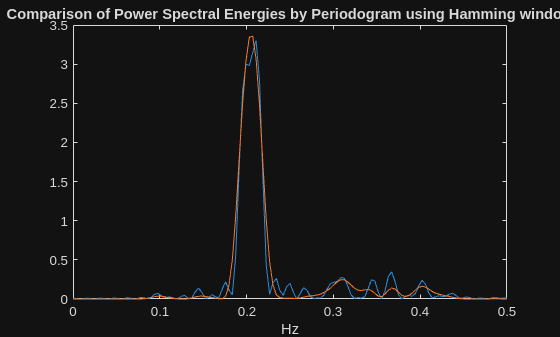

factor= sum(marple.^2)/sum(wmarple.^2);
Pxxfw=factor*Pxxfw;
plot(f, Pxxf, f, Pxxfw);
xlabel('Hz');
title('Comparison of Power Spectral Energies by Periodogram using Hamming window');